function projections = project_points(points, f, alpha_x, alpha_y, o_r, o_c, p)
    % Project 3D points onto a 2D plane (CCD) using camera parameters.
    %
    % Args:
    % - points: A Nx3 matrix of 3D points in the form [X1, Y1, Z1; X2, Y2, Z2; ...].
    % - f: Focal length in mm.
    % - alpha_x: Pixel scale in x direction (pixels per mm).
    % - alpha_y: Pixel scale in y direction (pixels per mm).
    % - o_r: Image center in the row (u) direction.
    % - o_c: Image center in the column (v) direction.
    % - p: Print the projected points with a label (true or false).
    %
    % Returns:
    % - projections: A Nx2 matrix of projected 2D points on the CCD in pixel coordinates.
    
    % Initialize projections array
    projections = zeros(size(points, 1), 2);
    
    for i = 1:size(points, 1)
        X = points(i, 1);
        Y = points(i, 2);
        Z = points(i, 3);
        
        % Calculate the projection onto the CCD
        u = -f * (X / Z) * alpha_x + o_r;
        v = -f * (Y / Z) * alpha_y + o_c;
        
        % Store the projected point (u, v)
        projections(i, :) = [u, v];
    end
    
    % Round the projections to 2 decimal places
    projections = round(projections, 2);
    
    if p
        % Print each projected point with a label
        for i = 1:size(projections, 1)
            fprintf('P%d = [%0.2f, %0.2f]\n', i, projections(i, 1), projections(i, 2));
        end
    end
end

function d = calculate_distance(f, alpha_x, alpha_y, o_r, o_c, real_dist, p1, p2)
    % Calculate the distance using given camera parameters and points.
    %
    % Args:
    % - f: Focal length in mm.
    % - alpha_x: Pixel scale in x direction (pixels per mm).
    % - alpha_y: Pixel scale in y direction (pixels per mm).
    % - o_r: Image center in the row (u) direction.
    % - o_c: Image center in the column (v) direction.
    % - real_dist: Real distance between points in mm.
    % - p1: First point in pixel coordinates (1x2 vector).
    % - p2: Second point in pixel coordinates (1x2 vector).
    %
    % Returns:
    % - d: Calculated distance.

    % Convert pixel coordinates to real-world coordinates
    p1_real = [p1(1) / alpha_x, p1(2) / alpha_y];
    p2_real = [p2(1) / alpha_x, p2(2) / alpha_y];
    
    % Calculate the pixel distance between the two points
    pixel_dist = sqrt((p1_real(1) - p2_real(1))^2 + (p1_real(2) - p2_real(2))^2);
    
    % Calculate the distance
    d = (f * real_dist) / pixel_dist;
end

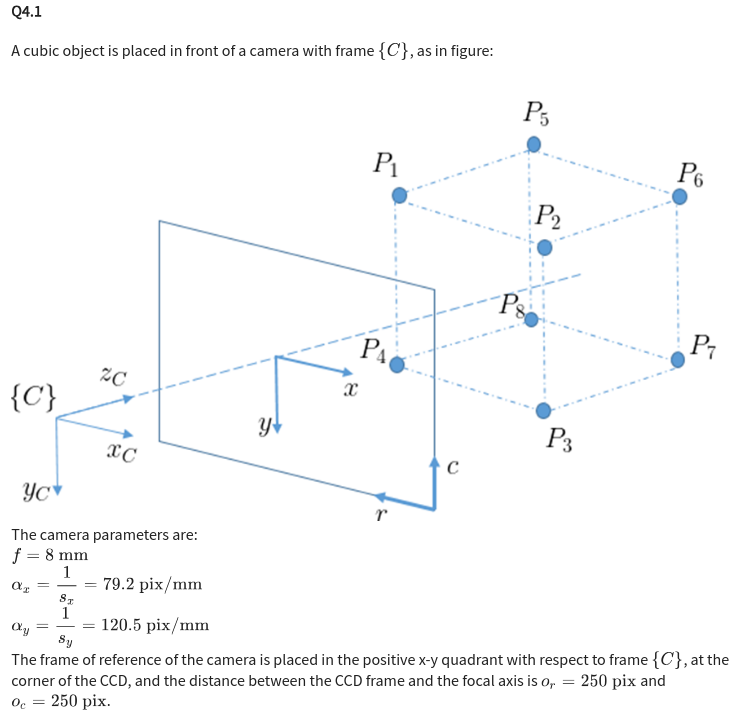

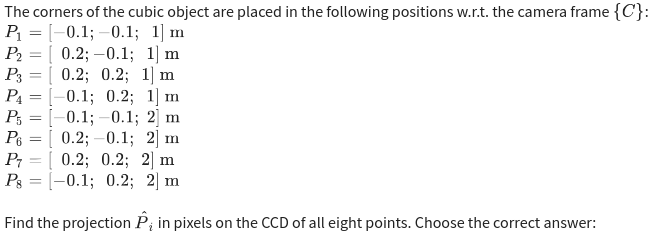

% Given camera parameters
f = 8;           % Focal length in mm
alpha_x = 79.2;  % Pixel scale in x direction (pixels per mm)
alpha_y = 120.5; % Pixel scale in y direction (pixels per mm)
o_r = 250;       % Image center row (u) in pixels
o_c = 250;       % Image center column (v) in pixels

% 3D points in the camera coordinate frame
points = [
    -0.1, -0.1, 1;
     0.2, -0.1, 1;
     0.2,  0.2, 1;
    -0.1,  0.2, 1;
    -0.1, -0.1, 2;
     0.2, -0.1, 2;
     0.2,  0.2, 2;
    -0.1,  0.2, 2
];

% Call the function
projections = project_points(points, f, alpha_x, alpha_y, o_r, o_c, true);

P1 = [313.36, 346.40]
P2 = [123.28, 346.40]
P3 = [123.28, 57.20]
P4 = [313.36, 57.20]
P5 = [281.68, 298.20]
P6 = [186.64, 298.20]
P7 = [186.64, 153.60]
P8 = [281.68, 153.60]


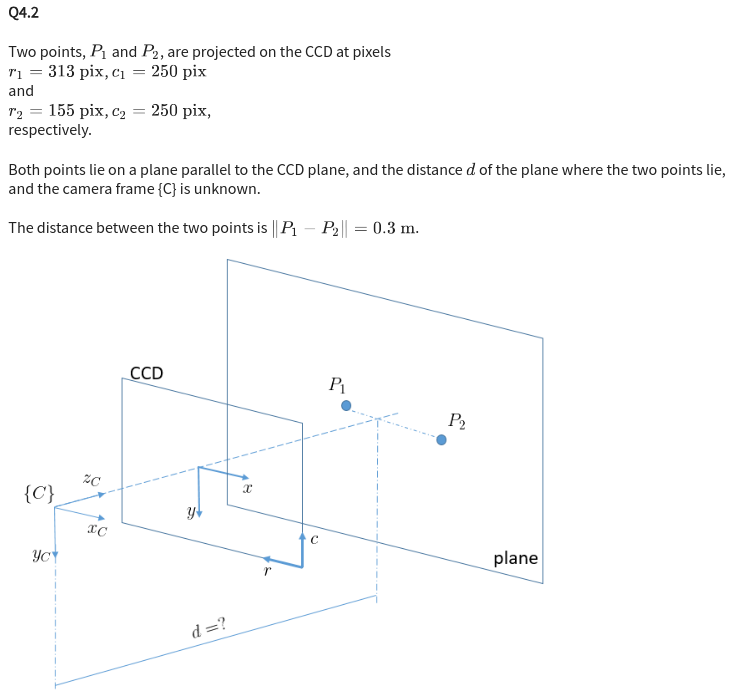

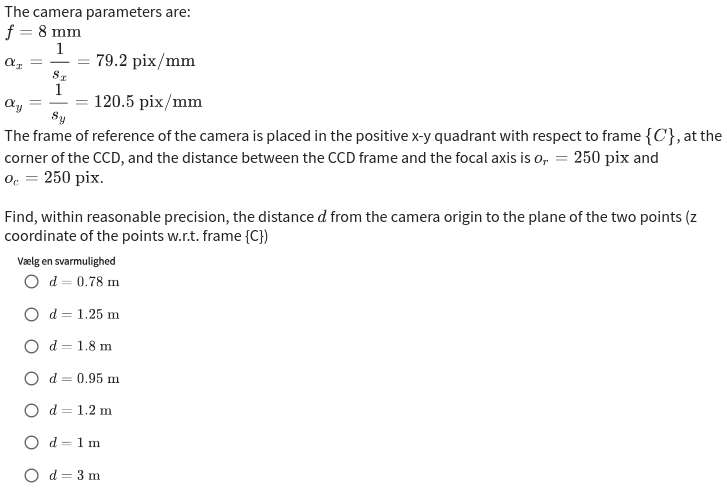

% Example usage
f = 8;                % Focal length in mm
alpha_x = 79.2;       % Pixel scale in x direction (pixels per mm)
alpha_y = 120.5;      % Pixel scale in y direction (pixels per mm)
o_r = 250;            % Image center row (u) in pixels
o_c = 250;            % Image center column (v) in pixels
real_dist = 0.3;      % Real-world distance between the points in mm
p1 = [313, 250];      % First point in pixel coordinates
p2 = [155, 250];      % Second point in pixel coordinates

% Calculate the distance
d = calculate_distance(f, alpha_x, alpha_y, o_r, o_c, real_dist, p1, p2);

% Display the result
fprintf('Calculated distance: %.2f mm\n', d);

Calculated distance: 1.20 mm
